n = 50;
x1 = 0.337;
x2 = 1e5;
r1 = 1.3;
r2 = 0.3;
data1 = zeros(1,n);
data2 = zeros(1,n);
for i = 1:n
    data1(i) = x1;
    data2(i) = x2;
    x1 = r1*x1;
    x2 = r2*x2;
end
figure;
plot(data1,'r');
legends{1} = sprintf("r = %.2f",r1);
hold on
plot(data2,'b');
legends{2} = sprintf("r = %.2f",r2);
legend(legends);

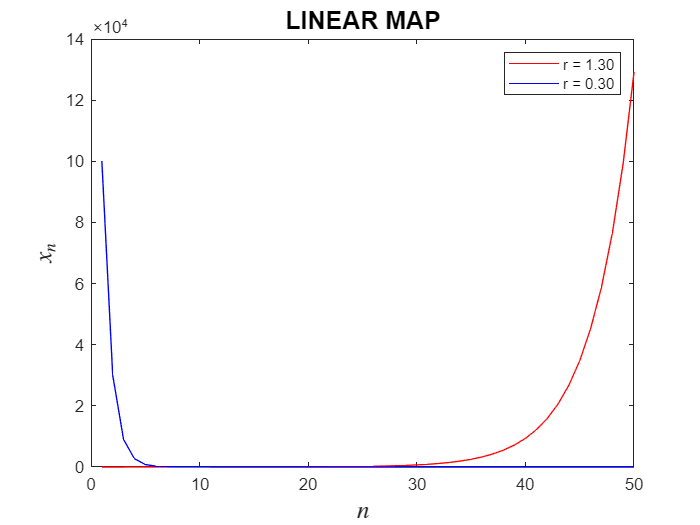

title("LINEAR MAP", FontSize=15);
xlabel("$n$",'Interpreter','latex',FontSize=15);
ylabel("$x_{n}$",'Interpreter','latex',FontSize=15); 

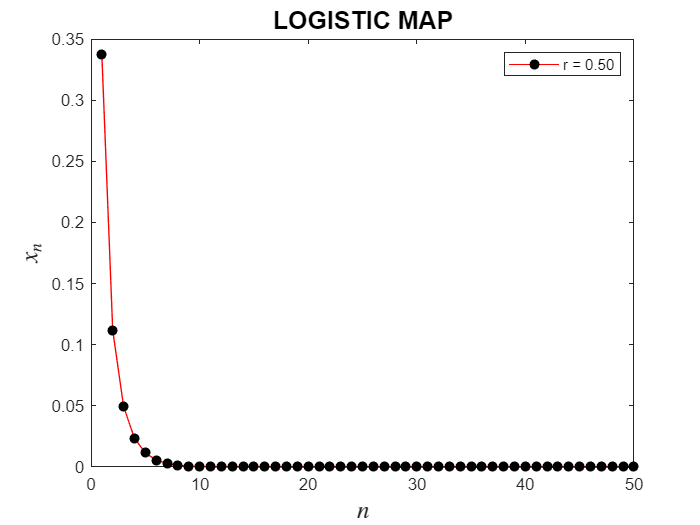

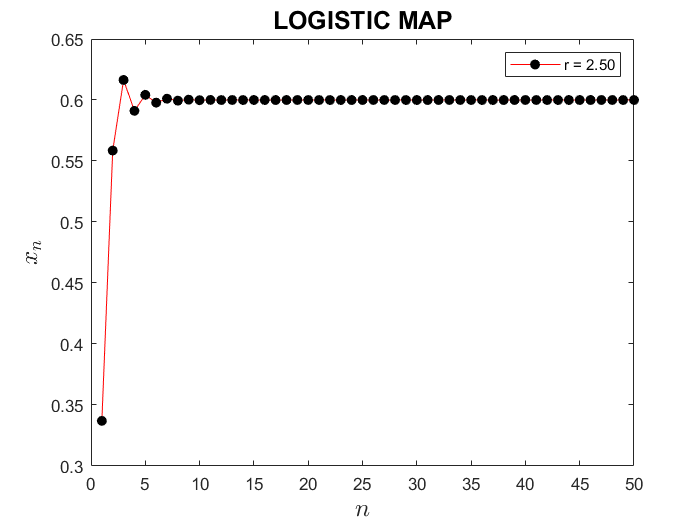

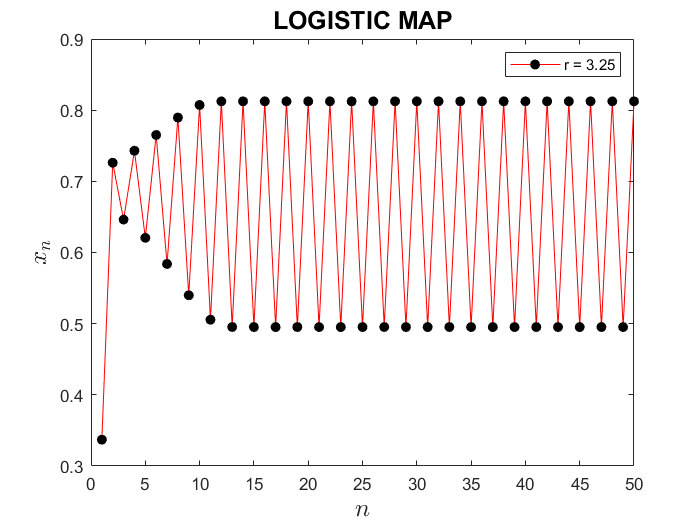

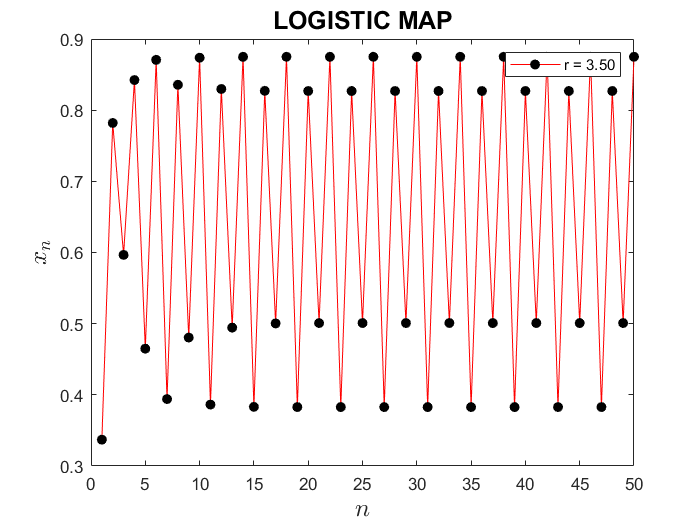

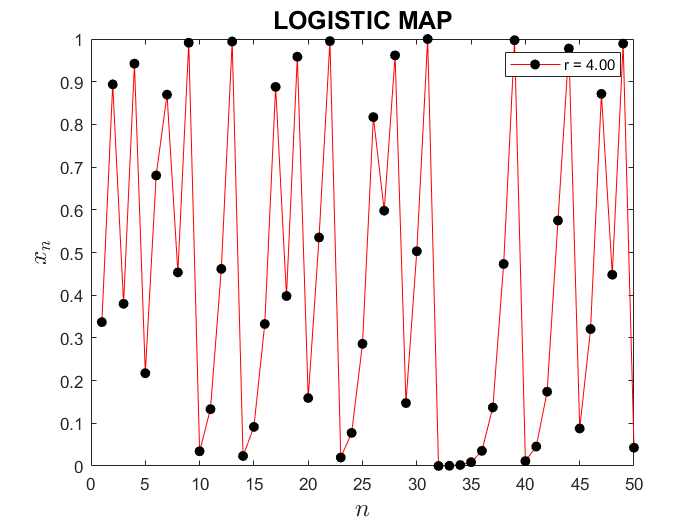

n = 50;
x = 0.337;
r = [0.5,2.5,3.25,3.5,4];
data = zeros(1,n);
for j=1:5
    for i = 1:n
        data(i) = x;
        x = r(j)*x*(1-x);
    end
    figure;
    plot(data,'r',Marker='o',MarkerFaceColor='black',MarkerEdgeColor='none');
    title("LOGISTIC MAP", FontSize=15);
    legend(sprintf("r = %.2f",r(j)));
    xlabel("$n$",'Interpreter','latex',FontSize=15);
    ylabel("$x_{n}$",'Interpreter','latex',FontSize=15); 
    data = zeros(1,n);
    x = 0.337;
end

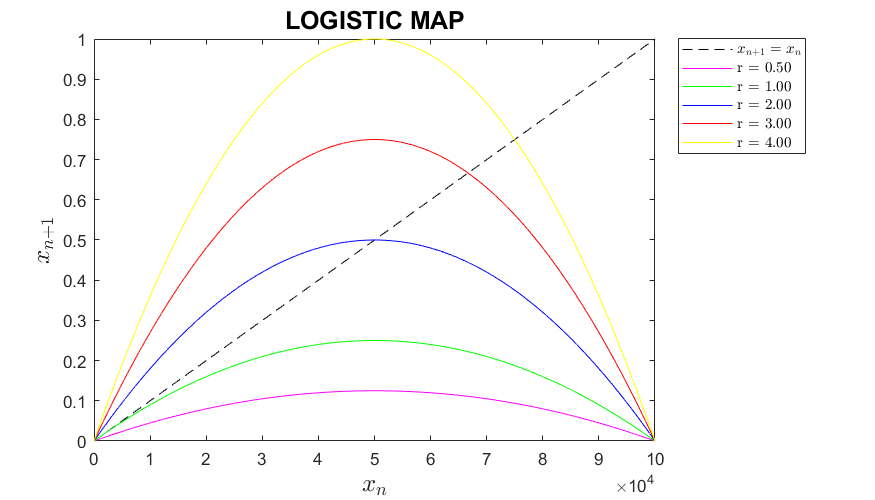

n = 100000;
x = linspace(0,1,n);
r = [0.5,1,2,3,4];
color = {'magenta','green','blue','red','yellow'};
figure;
plot(x,'--','color','black');
legends{1} = "$x_{n+1}=x_{n}$";
hold on
for j=1:length(r)
    data = r(j).*x.*(1-x);
    plot(data, color{j});
    hold on
    title("LOGISTIC MAP", FontSize=15);
    legends{j+1} = sprintf("r = %.2f",r(j));
    xlabel("$x_{n}$",'Interpreter','latex',FontSize=15);
    ylabel("$x_{n+1}$",'Interpreter','latex',FontSize=15); 
end
legend(legends, 'Interpreter', 'latex','location','northeastoutside');
set(gcf,'position',[0,0,700,400]);

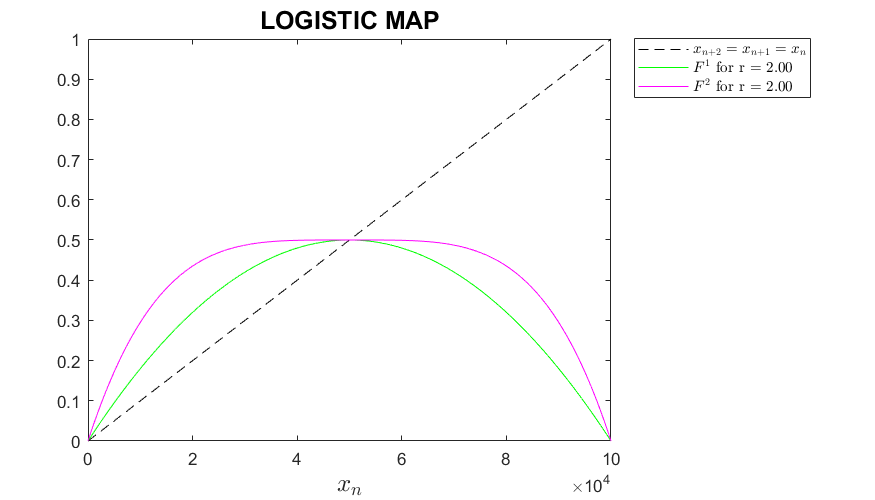

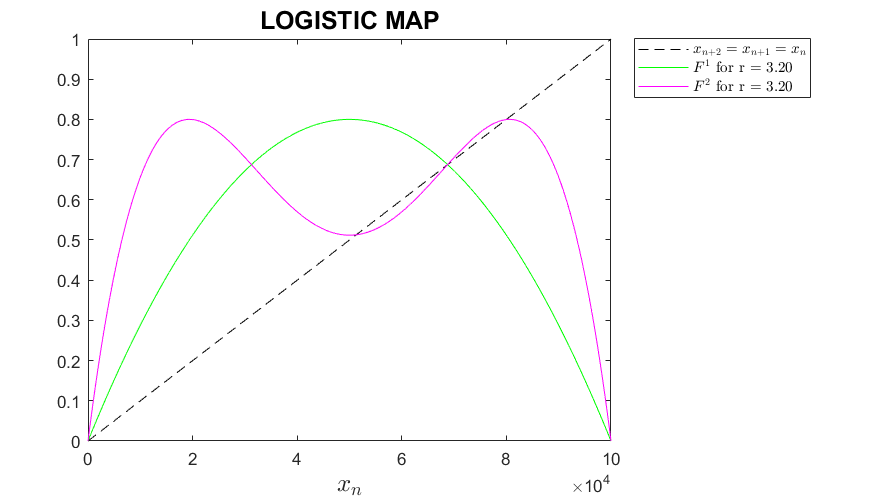

n = 100000;
x = linspace(0,1,n);
r = [2,3.2];
color = {'green','magenta'};
data = zeros(size(x));
for j=1:length(r)
    figure;
    plot(x,'--','color','black');
    hold on
    legends{1} = "$x_{n+2}=x_{n+1}=x_{n}$";
    for i=1:2        
        data = r(j).*x.*(1-x);
        x = r(j).*x.*(1-x);
        plot(data, color{i});
        hold on
        legends{i+1} = sprintf("$F^{%d}$ for r = %.2f",[i,r(j)]);
    end
    title("LOGISTIC MAP", FontSize=15);
    xlabel("$x_{n}$",'Interpreter','latex',FontSize=15);
    data = zeros(size(x));
    x = linspace(0,1,n);
    legend(legends, 'Interpreter','latex', 'location','northeastoutside');
    set(gcf,'position',[10,10,700,400]);
end